# Control Systems continuos domain

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



G=tf([-1,1],[1,2,1])/s    %% open loop transfer functyion

G =
 
      -s + 1
  ---------------
  s^3 + 2 s^2 + s
 
Continuous-time transfer function.



K=1      %%controller transfer function

K = 1



H=feedback(G*K,1)           %%closed loop transfer function G*K/(1+G*K)

H =
 
      -s + 1
  ---------------
  s^3 + 2 s^2 + 1
 
Continuous-time transfer function.



E=-1/(1+G*K)             %%error transfer function

E =
 
  -s^3 - 2 s^2 - s
  ----------------
  s^3 + 2 s^2 + 1
 
Continuous-time transfer function.



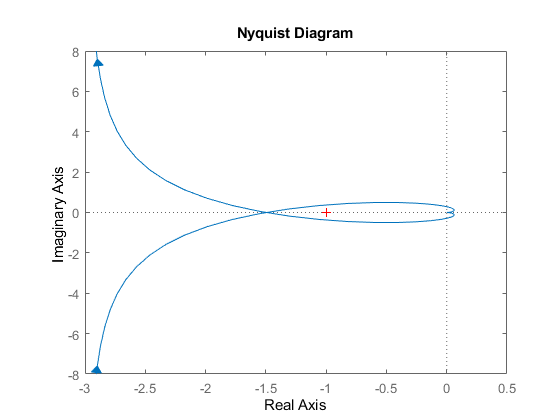


nyquist(G)

nyquist(G*K)


Margin_1=allmargin(G)   %%margins for open loop

Margin_1 = struct with fields:
     GainMargin: 0.6666
    GMFrequency: 0.5773
    PhaseMargin: -24.5181
    PMFrequency: 0.7862
    DelayMargin: 7.4480
    DMFrequency: 0.7862
         Stable: 0


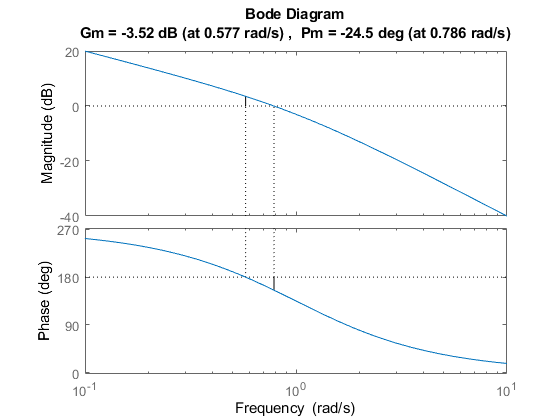

margin(G)


Margin_K=allmargin(G*K) %%margins for open loop with controller

Margin_K = struct with fields:
     GainMargin: 0.6666
    GMFrequency: 0.5773
    PhaseMargin: -24.5181
    PMFrequency: 0.7862
    DelayMargin: 7.4480
    DMFrequency: 0.7862
         Stable: 0


margin(K*G)

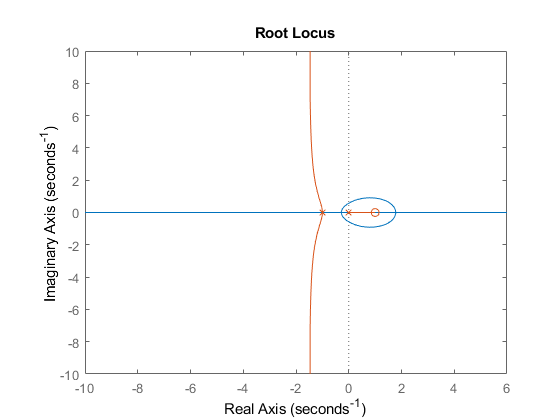


rlocus(G,-1*G)               %%root locus diagram for all k copy into console for black box

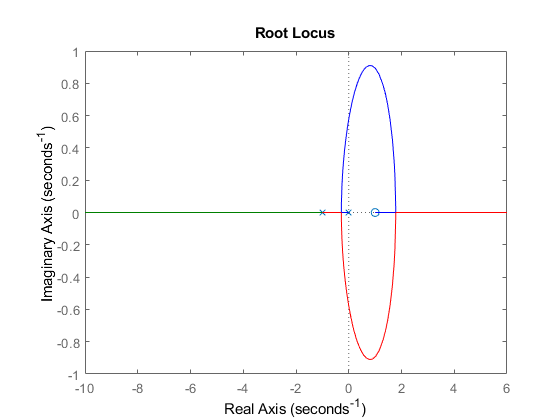

rlocus(G)               %root locus diagram for +ve k copy into console for black box

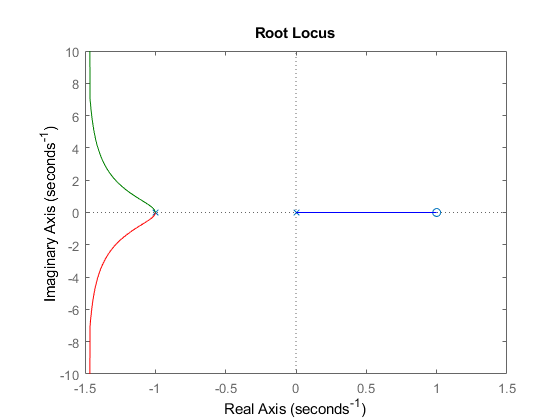

rlocus(-1*G)            %%root locus diahram for +ve k copy into console for black box

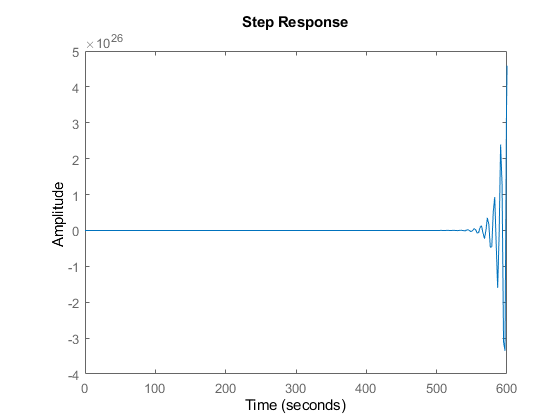


step(H)                 %% closed loop step response

step(E)


isstable(H)             %% check if closed loop is stable

ans = logical
   0


stepinfo(H)

ans = struct with fields:
        RiseTime: NaN
    SettlingTime: NaN
     SettlingMin: NaN
     SettlingMax: NaN
       Overshoot: NaN
      Undershoot: NaN
            Peak: Inf
        PeakTime: Inf



%R=myRouthMKII(G)





function R = myRouthMKII(sys)
    %% ROUTH-HURWITZ Array
    %
    % Examples: 
    %
    % 1. P = s^4 + 10*s^3 + 35*s^2 + 50*s + 24 ;
    %    R = myRouth( [1 10 35 50 24] )
    %
    % 2. syms a b c d s , P = s^4 + a*s^3 + b*s^2 + c*s + d ; 
    %    R = myRouth( [1 a b c d] )
    %
    % 3. syms K , P = s^2 + (12-3*K)*s + 20+0.25*K ; 
    %    R = myRouth( [1 12-3*K 20+0.25*K] )
    syms k1 k2 k3 x
    [num,den]=tfdata(sys);   %%numerator and denominator of G
    
    top=poly2sym(num,x)     %%into polynomial
    bot=poly2sym(den,x)
    full=top/bot
    
    PID=k1+k2*x+k3/x
    
    H=(PID*full)/(1+PID*full)
    
    [n,d]=numden(H)
    b=sym2poly(n-d)
    
    %% Polynomial coefficients as input
    if(nargin<1), warning('No Input Argument') ; return
    end
    
    %% Flip vector in left/right direction and find order of polynomial
    b = fliplr(b) ;      
    ord = size(b,2)-1 ; 
    
    % It gives the index number of R11's row  
    % ord = 6,7 --> rou_i = 7
    rou_i = fix( fix(ord/2)*2 ) + 1 ;
    rou_j = ceil((ord+1)/2) ;             % Round infinity
    
    %% If order is even add one zero as a last element of matrix
    Ri = [ b(ord+1:-2:1) ; 
           b(ord:-2:1)  zeros( fix(( rou_i-1 )/ord) ) ] ;
    
    R = sym( zeros(ord+1,rou_j) )  ;  R(ord+1:-1:ord, : ) = Ri ;
    
    %% All R's for Routh-Hurwitz [Main Algorithm]
    for n = ord-1:-1:2
    for j = 1:round(n/2)
    R(n,j) = ( R(n+1,1)*R(n+2,j+1)-R(n+1,j+1)*R(n+2,1) )/R(n+1) ;
    end
    end
    R(1,1) = R(rou_i,rou_j) ;
    
    %% Simplify and Flip matrix in up/down direction.
    R = simplify(R) ; R = flipud(R) ; 

end